% Define las ecuaciones diferenciales
syms x y
% Exercise 2-1
% a)
fx = x-y-x*(x^2+5*y^2)

$$fx = x-y-x\,\left(x^{2}+5\,y^{2}\right)$$

fy = x+y-y*(x^2+y^2)

$$fy = x+y-y\,\left(x^{2}+y^{2}\right)$$

% setting the matlab function for our system
f_lmb = @(t,z) [z(1) - z(2) - z(1)*(z(1)^2 + 5*z(2)); z(1) + z(2) - z(2)*(z(1)^2 + z(2))];

% 1. CALCULATE THE FIXED POINTS
fixPts = solve([fx; fy], [x; y])

fixPts = struct with fields:
    x: [9×1 sym]
    y: [9×1 sym]


fixPts = double([fixPts.x'; fixPts.y'])

fixPts =    0.0000 + 0.0000i  -1.5404 + 0.9750i   1.5404 + 0.9750i   1.5404 - 0.9750i  -1.5404 - 0.9750i   0.3034 - 0.1196i  -0.3034 - 0.1196i  -0.3034 + 0.1196i   0.3034 + 0.1196i
   0.0000 + 0.0000i  -0.4665 - 0.5590i   0.4665 - 0.5590i   0.4665 + 0.5590i  -0.4665 + 0.5590i  -0.7943 - 0.1897i   0.7943 - 0.1897i   0.7943 + 0.1897i  -0.7943 + 0.1897i



% Computing the jacobian matrix and the eigenvalues for the fixed points
JacFixPts = zeros(2, 2, size(fixPts, 2));
eigenvalues = zeros(size(fixPts, 2), 2);
eigenvectors = zeros(2, 2, size(fixPts, 2));

for k = 1:size(fixPts, 2)
    JacFixPts(:,:,k) = double(subs(jacobian([fx, fy], [x, y]), {x, y}, {fixPts(1, k), fixPts(2, k)}));
    [eigenvectors(:,:,k), D] = eig(JacFixPts(:,:,k));
    eigenvalues(k, :) = diag(D);
end

% 2. IDENTIFY IF THE FIXED POINTS ARE HYPERBOLIC
% 3. CLASSIFICATION OF THE FIXED POINTS
for k =1:size(fixPts, 2)
    if all(real(eigenvalues(k, :)) == 0)
        fprintf('Fixed point at (%f, %f) is hyperbolic.\n', fixPts(1, k), fixPts(2, k));
    else
        fprintf('Fixed point at (%f, %f) is not hyperbolic.\n', fixPts(1, k), fixPts(2, k));
    end
end

Fixed point at (0.000000, 0.000000) is not hyperbolic.
Fixed point at (-1.540430, -0.466509) is not hyperbolic.
Fixed point at (1.540430, 0.466509) is not hyperbolic.
Fixed point at (1.540430, 0.466509) is not hyperbolic.
Fixed point at (-1.540430, -0.466509) is not hyperbolic.
Fixed point at (0.303423, -0.794286) is not hyperbolic.
Fixed point at (-0.303423, 0.794286) is not hyperbolic.
Fixed point at (-0.303423, 0.794286) is not hyperbolic.
Fixed point at (0.303423, -0.794286) is not hyperbolic.



% Represent the fixed points and the eigenvalues
h1 = figure;
hold on;
grid on;
fpts = plot(fixPts(1,:), fixPts(2,:), 'o', 'MarkerFaceColor', 'r');



% 4. COMPUTE THE NULLCLINES
xcline_x = solve(fx == 0, y);
ycline_y = solve(fy == 0, y);

% Representing the nullclines
nullX = fimplicit(fx, [-8 8 -8 8], 'r--', 'LineWidth', 1.5);
nullY = fimplicit(fy, [-8 8 -8 8], 'g--', 'LineWidth', 1.5);

% 6. REPRESENT FLOW IN A GRID 10X10
% Campo vectorial
N = 20; % tamaño de la cuadrícula
xlin = linspace(-8, 8, N);
ylin = linspace(-8, 8, N);
[Xgrid, Ygrid] = meshgrid(xlin, ylin);
% Computing the grid
fx_grid = subs(fx, [x, y], {Xgrid, Ygrid});
fy_grid = subs(fy, [x, y], {Xgrid, Ygrid});

magnitude = sqrt(fx_grid.^2 + fy_grid.^2);
fx_normalized = fx_grid ./ magnitude;
fy_normalized = fy_grid ./ magnitude;

% Computing the flow of the system with quiver
flow = quiver(Xgrid, Ygrid, fx_normalized, fy_normalized, 'AutoScale', 'on', 'AutoScaleFactor', 0.25, 'Color', 'k');

axis([-8 8 -8 8]);
xlabel('x');
ylabel('y');
title('Campo vectorial con puntos fijos, eigenvalores y nullclines');

% 7. DRAW THE PHASE PORTRAIT
% 5. REPRESENT A TRAJECTORY
% Initialise at (1, 0.5)
y0 =[1 0.5];
t0 = 0.5; tf = 100;
tspam = [t0,tf];
[ts,ys] = ode45(f_lmb,tspam, y0);
traj1 = plot(ys(:,1),ys(:,2),'b-'); plot(y0(1),y0(2),'o','MarkerFaceColor','b');

% Initialise at (0.5, 2)
y0 =[0.5 2];
tspam = [t0,tf];
[ts,ys] = ode45(f_lmb,tspam, y0);
traj2 = plot(ys(:,1),ys(:,2),'b-'); plot(y0(1),y0(2),'o','MarkerFaceColor','b');

% 8. REPRESENT THE BASINS OF ATTRACTION IN THE PHASE DIAGRAM
% 9. PAINT A TRAJECTORY FOR EACH BASIN
eps = 1e-3

eps = 1.0000e-03

y0 = (eigenvectors(:, 1, 1)*eps)+fixPts(:,1)

y0 = 	1.0e+-3 *

   0.7071 + 0.0000i
   0.0000 - 0.7071i


tspam = [t0,tf];
[ts,ys] = ode45(f_lmb,tspam, y0);
basin1 = plot(ys(:,1),ys(:,2),'r-');


y0 = -(eigenvectors(:, 1, 1)*eps)+fixPts(:,1)

y0 = 	1.0e+-3 *

  -0.7071 + 0.0000i
   0.0000 + 0.7071i


tspam = [t0,tf];
[ts,ys] = ode45(f_lmb,tspam, y0);
basin2 = plot(ys(:,1),ys(:,2),'r-');


y0 = (eigenvectors(:, 2, 1)*eps)+fixPts(:,1)

y0 = 	1.0e+-3 *

   0.7071 + 0.0000i
   0.0000 + 0.7071i


tspam = [tf,t0];
[ts,ys] = ode45(f_lmb,tspam, y0);
basin3 = plot(ys(:,1),ys(:,2),'black-');


y0 = -(eigenvectors(:, 2, 1)*eps)+fixPts(:,1)

y0 = 	1.0e+-3 *

  -0.7071 + 0.0000i
   0.0000 - 0.7071i


tspam = [tf,t0];
[ts,ys] = ode45(f_lmb,tspam, y0);
basin4 = plot(ys(:,1),ys(:,2),'black-');

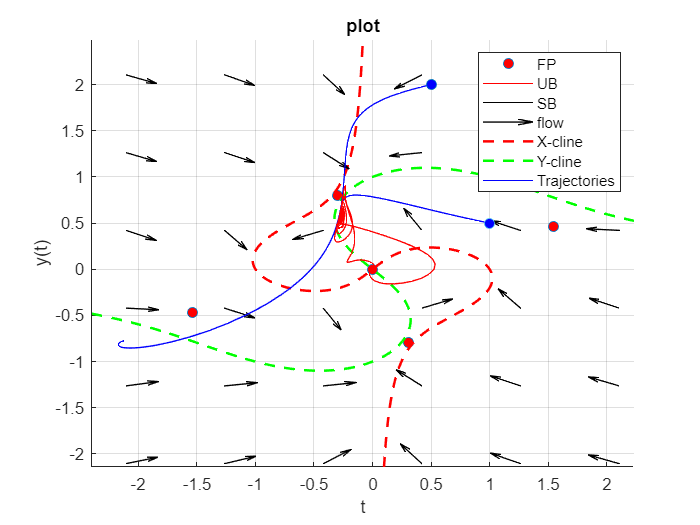

xlabel('t');ylabel('y(t)');grid on; title('plot')

legend([fpts basin1 basin3 flow nullX nullY traj1], ...
    {'FP', 'UB', 'SB', 'flow', 'X-cline', 'Y-cline', 'Trajectories'}, ...
    'Location', 'NorthEast')


disp(['There is no saddle node, so no basins are painted.' ...
    'Also, every trajectory, no matter the initial conditions will lead to the extinction of sheeps.'])

There is no saddle node, so no basins are painted.Also, every trajectory, no matter the initial conditions will lead to the extinction of sheeps.
